# Actividad 8.1_3

### Diego Garcia Rueda

#### **Obtener **la matriz de  transformación **homogénea  T  **de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

Primero se realizan los comandos de limpieza de pantalla y de workspace.

clear all
close all
clc

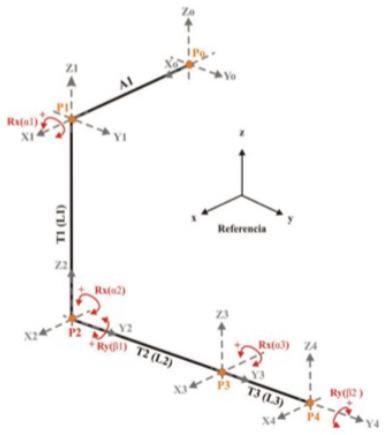

Se calculan las matrices de transformación Homogénea del modelo, el valor de A1, T1, T2 y T3 tendra un valor de 2, las transformaciones serán las siguientes:

m3_H0 = SE3

 

m3_H0 = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


m3_H1 = SE3(rotx(0), [2,0,0])

 

m3_H1 = 
         1         0         0         2
         0         1         0         0
         0         0         1         0
         0         0         0         1


m3_H2 = SE3(rotx(0), [0,0,-2])

 

m3_H2 = 
         1         0         0         0
         0         1         0         0
         0         0         1        -2
         0         0         0         1


m3_H3 = SE3(rotx(0), [0,2,0])

 

m3_H3 = 
         1         0         0         0
         0         1         0         2
         0         0         1         0
         0         0         0         1


m3_H4 = SE3(rotx(0), [0,2,0])

 

m3_H4 = 
         1         0         0         0
         0         1         0         2
         0         0         1         0
         0         0         0         1


Se realizan las matrices de transformación globales.

m3_H20 = m3_H1 * m3_H2;
m3_H30 = m3_H20 * m3_H3;
m3_H40 = m3_H30 * m3_H4;

Se establecen valores para los 3 ejes, estas seran las coordenadas con las traslaciones y las rotaciones de todas las transformaciones:

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se establece la trama absoluta o global y posteriormente se realizan las animaciones para cada una de las tramas:

trplot(m3_H0,'rgb','axis', [-6 6 -6 6 -6 6])

%Primera trama
pause;
tranimate(m3_H0, m3_H1,'rgb','axis', [-6 6 -6 6 -6 6])
%Segunda trama
pause;
tranimate(m3_H1, m3_H20,'rgb','axis', [-6 6 -6 6 -6 6])
%Tercera trama
pause;
tranimate(m3_H20, m3_H30,'rgb','axis', [-6 6 -6 6 -6 6])
%Cuarta trama
pause;
tranimate(m3_H30, m3_H40,'rgb','axis', [-6 6 -6 6 -6 6])


disp(m3_H40)

    1         0         0         2
    0         1         0         4
    0         0         1        -2
    0         0         0         1
